# Dynamic simulation using complementarity methods (I)

Author: Jiayin Xie 

Date: August 18 2020

## Introduction to the PATH solver

The Path solver is a newton-based solver for mixed complementarity problems (MCP). Our dynamic model is formulated as MCP, so it can be solved by PATH.

### MCP problem definition

(General) Let $l\in R^{n\;}$be the vector of lower bounds,  $u\in R^{n\;}$ be the vector of upper bounds, and $l<u$. $n$ is the number of equations and unknown variables. Let $B:=\left\lbrace z\in R^n \left|l\le z\le u\right.\right\rbrace$ and $F:B\to R^n$. The vector $z\in B$ is a solution to MCP $\left(F,B\right)$, if and only if the following holds for each $i\in \left\lbrace 1,\ldotp \ldotp \ldotp ,n\right\rbrace :$


$$\begin{array}{l}
l_{i\;} \le z_i \le u_i \;\;\textrm{and}\;F_i \left(z\right)=0\\
z_i =l_i \;\textrm{and}\;F_i \left(z\right)>0\\
z_i =u_i \;\textrm{and}\;F_i \left(z\right)<0
\end{array}$$
  

(Specified) Let the unknown variables $\mathit{\mathbf{z}}={\left\lbrack {\mathit{\mathbf{z}}}_u ,{\mathit{\mathbf{z}}}_v \right\rbrack }^T \;,\textrm{where}\;\;{\mathit{\mathbf{z}}}_u \in R^{n_1 } \;,{\mathit{\mathbf{z}}}_v \in R^{n_2 } \;$. Let $l={\left\lbrack l_u ,l_v \right\rbrack }^T ,u={\left\lbrack u_u ,u_v \right\rbrack }^T$, where $l_u \le z_u \le u_u ,\;l_v \le z_v \le u_v \ldotp$  And we let  $F=\left\lbrack \mathit{\mathbf{g}},\mathit{\mathbf{f}}\right\rbrack ,\textrm{where}\;$$\mathit{\mathbf{g}}:R^{n_1 } \times R^{n_2 } \to R^{n_1 }$ and $\mathit{\mathbf{f}}:$$R^{n_1 } \times R^{n_2 } \to R^{n_2 }$ are two vector functions. By choosing $l_u \equiv -\infty ,u_u \equiv +\infty ,$ and $l_v \equiv 0,u_v \equiv +\infty$,  the specified MCP model can be: 

                                                                      
$$\begin{array}{l}
\mathit{\mathbf{g}}\left({\mathit{\mathbf{z}}}_u ,{\mathit{\mathbf{z}}}_v \right)=0\\
0\le {\mathit{\mathbf{z}}}_v \bot \mathit{\mathbf{f}}\left({\mathit{\mathbf{z}}}_u ,{\mathit{\mathbf{z}}}_v \right)\ge 0
\end{array}$$


### The function 'pathmcp' 

 [z,f,J,mu,status] = pathmcp(z,l,u,cpfj,A,b,t,mu)

Inputs:

- z - Initial guess (colum vector) for newton-based method

- l - lower bound vectors. u - upper bound vectors. 

- cpfj - the name of the m-file for evaluating the function f and its Jacobian J.

Outputs:

- z - solution

- f,J - evaluations

- status - 1 for success and 0 for fail

x = pathmcp(rand(11,1),zeros(11,1),inf*ones(11,1),'mcp_funjac')

x =    22.5041
  302.4959
         0
  293.8260
         0
  281.1740
    1.0556
    0.9836
    0.9566
    0.8306


f = mcp_funjac(x,0)

f =     0.0000
    0.0000
    0.0360
   -0.0000
    0.0090
    0.0000
         0
         0
         0
         0


resid = f'*x

resid = 3.1158e-14

### Options for PATH in 'path.opt'

%convergence_tolerance 1e-6;

## Dynamic Simulation

### Problem statement

Given the state (configuration $\mathit{\mathbf{q}}$ and velocity $\nu \;$) and applied impulse ${\mathit{\mathbf{p}}}_{\textrm{app}}$, predict or compute the state and contact wrenches one time step into the future.

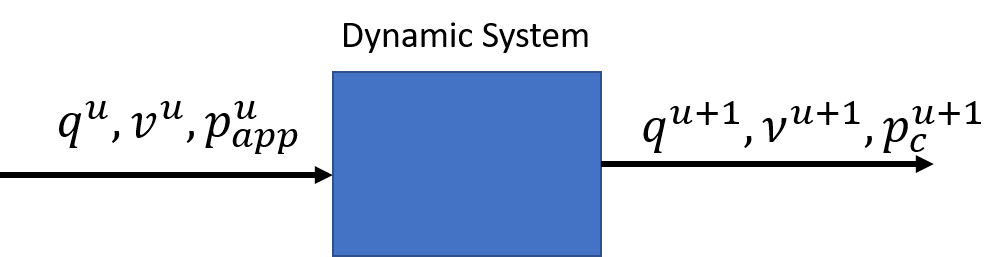

### Dynamic System

In our MCP-based dynamic model, $\textrm{The}\;\textrm{unknown}\;\textrm{variables}\;\textrm{includes}\;\textrm{two}\;\textrm{parts}:\;{\mathit{\mathbf{z}}}_u =\;{\left\lbrack \nu \;,{\mathit{\mathbf{a}}}_1 ,{\mathit{\mathbf{a}}}_2 ,p_t ,p_o ,p_r \right\rbrack }^T \;\textrm{and}\;\;{\mathit{\mathbf{z}}}_v ={\left\lbrack \lambda ,\sigma ,p_n \right\rbrack }^T \ldotp$ 

The equality constraints are: $\mathit{\mathbf{g}}\left({\mathit{\mathbf{z}}}_{\mathit{\mathbf{u}}} ,{\mathit{\mathbf{z}}}_{\mathit{\mathbf{v}}} \right)=0$, and the complementarity constraints are: $0\le {\mathit{\mathbf{z}}}_v \bot \mathit{\mathbf{f}}\left({\mathit{\mathbf{z}}}_u ,{\mathit{\mathbf{z}}}_v \right)\ge 0$. The PATH solver is a newton-based method:


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;z^{{\;}^{u+1} } =z^u -J_F {\left(z^{u\;} \right)}^{-1} F\left(z^u \right)$$
 

where $J_F \left(z^{u\;} \right)\;$is the jacobian matrix evaluated at $z^{u\;}$ and $F\left(z^{u\;} \right)$is the function value evaluated at $z^{u\;}$. Note that functions $\mathit{\mathbf{F}}={\left\lbrack \mathit{\mathbf{g}},\mathit{\mathbf{f}}\right\rbrack }^{\mathit{\mathbf{T}}} \ldotp$ In PATH solver, the evaluations for $J_F \left(z^{u\;} \right)$ and $F\left(z^{u\;} \right)$ are in function 'cpfj.m' (see 'mcp_point.m' in appendix for detail).

### Loops for the dynamic simulation

As we have stated, given the configuration, the states, and applied impulses $q^u ,v^u ,{p^u }_{\textrm{app}}$, we try to predict or compute the states $v^{u+1}$and contact wrenches $p_c^{u+1} \;$one step in the future. Thus, in a loop, we use PATH solver to solve our system of equations at each iteration or time step.

- The function 'pathmcp' takes ${\mathit{\mathbf{z}}}^u$ as the initial guess. When $u=1$, the user needs to provide a guess (initial_guess.m and change_initial_guess.m).

- The ${\mathit{\mathbf{z}}}^{u+1}$is returned by function 'pathmcp'.

- The PATH solver may fail to solve the problem. Thus,  the initial guess needs to be recomputed (change_guess.m). 

- After the $v^{u+1}$is computed, the configuration $q^{u+1} =q^u +{\textrm{hv}}^{u+1}$needs to be updated (kinematic_map.m).

- You can control the convergence (e.g. 'convergence_tolerance 1e-12') in the 'path.opt' file.

- An template loop function 'NCP_point.m' is provided in the appendix.

## Examples of a ellipse and ground

### Interface script

In the interface script, we first create a structure array to store the parameters ( inertia, friction, dimension, etc), the initial configuration and state, and the solution at each time step. Besides, the number of time steps and applied impulses at each time step is in the custom function 'planner_xx.m'. In the example of particle, we visualize the system using  'movie_ellpise.m' function.

%% notation
% l - beginning of current time step
% l+1 - end of current time step
clear all
close all
cd('..');
addpath('convex_contact_patches_interface');
addpath('visualize');
addpath('utility');
addpath('funjac');
addpath('pathmexmaci64');

cd('convex_contact_patches_interface')

A = struct();
% object
A.object = 'ellipse';
% mass of the object
A.mass = 3; %(kg)
A.gravity = 9.8; %(m/s^2)

% approximate dimension of the object 
%A.dim=[0.5 0.5 0.5]; %(m) length width height

% friction model
A.ellipsoid = [1 1 0.1]; 
A.cof = 0.22;

% time step
A.h = 0.01; %(s)

% initial state and configuration
A.initial_q = [-1;-1;1;1;0;0;0]; % m
A.initial_v = [2;2;0;0;2;0];  %m/s

% dimension of the ellipse
A.dim = [0.1 0.1 0.05]; %r_a r_b r_c


% unit
A.unit = 1; % 1 - m, 10 - dm, 100 - cm, 1000 - mm  

% impulses
A = planner_point(A);

% loops
A = NCP_loop(A);

% visualize

%movie_ellipse(A);
%movie_point(A);


## Useful resources and documents:

website:[http://pages.cs.wisc.edu/~ferris/path.html](http://pages.cs.wisc.edu/~ferris/path.html)

Latest documents: [https://www.gams.com/latest/docs/S_PATH.html](https://www.gams.com/latest/docs/S_PATH.html)

## Appendix:

### The cpfj file: 'mcp_funjac_point.m'

function [F, J, domerr] = mcp_funjac_point(z, jacflag)

%% initialize
z = z(:);
F = [];
J = [];
domerr = 0;

%% obtain value of global variables
global h;


status = 0

global q_old ;
q_xo = q_old(1);
q_yo = q_old(2);
q_zo = q_old(3);

global nu_old;
v_xo =nu_old(1);
v_yo =nu_old(2);
v_zo =nu_old(3);

global m mu e_o e_t g;

global p_x p_y p_z;

%% unknown variables

v_x = z(1);
v_y = z(2);
v_z = z(3);

p_t = z(4);
p_o = z(5);

sig = z(6);
p_n = z(7);


%% intermediate variables appear in the chain rule
% z - vector of unknown variables 

% The intermediate variables are:
% 1. [qo(z) q1(z) q2(z) q3(z)] - Quaternions, which depends on z
% 2. Rij(qo,q1,q2,q3) - elements in rotation matrix, which depends on the quaternion
% 3. Iij(qo,q1,q2,q3) - elements in RIR', which depends on the quaternion
% 4. q_x(z),q_y(z),q_z(z) - position vector in l+1, which depends on q_old and z

% Thus system of equations F can be described by the unknown variables z or
% with intermediate variables:
% 1. F(z,Rij,Iij,q_x,q_y,q_z) - F descriabed by z with intermediate variables
% 2. F(z) - F described by unknown variables z

% Based on the chain rule, Jocobain J = J1*J2*J3 where:
% J - dF(z)/dz Jacobian matrix 
% J1 = dF(z,Rij,Iij,q_x,q_y,q_z)/d[z,Rij,Iij,q_x,q_y,q_z] 
% J2 = d[z,Rij(qo,q1,q2,q3),Iij(qo,q1,q2,q3),q_x(z),q_y(z),q_z(z)]/d[z,qo,q1,q2,q3] 
% J3 = d[z,qo(z),q1(z),q2(z),q3(z)]/dz 

% q0 = -(2*((h*q1_o*w_x)/2 - q0_o + (h*q2_o*w_y)/2 + (h*q3_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
% q1 = (2*(q1_o + (h*q0_o*w_x)/2 + (h*q3_o*w_y)/2 - (h*q2_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
% q2 = (2*(q2_o - (h*q3_o*w_x)/2 + (h*q0_o*w_y)/2 + (h*q1_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
% q3 = (2*(q3_o + (h*q2_o*w_x)/2 - (h*q1_o*w_y)/2 + (h*q0_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);

q_x = q_xo+h*v_x;
q_y = q_yo+h*v_y;
q_z = q_zo+h*v_z;

% R11 = q0^2 + q1^2 - q2^2 - q3^2;
% R12 = 2*q1*q2 - 2*q0*q3;
% R13 = 2*q0*q2 + 2*q1*q3;
% R21 = 2*q0*q3 + 2*q1*q2;
% R22 = q0^2 - q1^2 + q2^2 - q3^2;
% R23 = 2*q2*q3 - 2*q0*q1;
% R31 = 2*q1*q3 - 2*q0*q2;
% R32 = 2*q0*q1 + 2*q2*q3;
% R33 = q0^2 - q1^2 - q2^2 + q3^2;
% 
% I11 = I_xx*R11^2 + I_yy*R12^2 + I_zz*R13^2;
% I12 = I_xx*R21*R11 + I_yy* R22*R12 + I_zz*R23*R13;
% I13 = I_xx*R31*R11 + I_yy* R32*R12 + I_zz*R33*R13;
% I21 = I12;
% I22 = I_xx*R21^2 + I_yy*R22^2 + I_zz*R23^2;
% I23 = I_xx*R31*R21 + I_yy*R32*R22 + I_zz*R33*R23;
% I31 = I13;
% I32 = I23;
% I33 = I_xx*R31^2 + I_yy*R32^2 + I_zz*R33^2;

%% system of equations f(x) == 0
% Newton_Euler equations
F(1) = p_t + p_x - m*(v_x - v_xo);
F(2) = p_o + p_y - m*(v_y - v_yo);
F(3) = p_n + p_z - m*(v_z - v_zo) - g*h*m;


% Friction Model without complementarity equation

F(4) = p_t*sig + e_t^2*mu*p_n*v_x;
F(5) = p_o*sig + e_o^2*mu*p_n*v_y;

% contact constraints without complementarity equation


% complementarity constraint in Friction Model
F(6) = mu^2*p_n^2 - p_t^2/e_t^2 - p_o^2/e_o^2;

% complementarity constraints in contact constraints

% non-penetration 
F(7) = q_z;


%% Jacobian matrix (Using chain rules) dF/d[z,q_x,q_y,q_z]*d[z,q_x,q_y,q_z]/dz

if (jacflag)
    J1 = [-m 0 0 1 0 0 0 0 0 0;
          0 -m 0 0 1 0 0 0 0 0;
          0  0 -m 0 0 0 1 0 0 0;
          e_t^2*mu*p_n 0 0 sig 0 p_t e_t^2*mu*v_x 0 0 0;
          0 e_o^2*mu*p_n 0 0 sig p_o e_o^2*mu*v_y 0 0 0;
          0 0 0 -2*p_t/e_t^2 -2*p_o/e_o^2 0 2*mu^2*p_n 0 0 0;
          0 0 h 0 0 0 0 0 0 1];
      
     J2 = [eye(7);
          h 0 0 0 0 0 0;
          0 h 0 0 0 0 0;
          0 0 h 0 0 0 0];
      
      J = J1*J2;
      J = sparse(J);
    
end
end

### The cpfj file: 'mcp_funjac_single_convex_contact_patch_ellipsoid.m'

function [F, J, domerr] = mcp_funjac_single_convex_contact_patch_ellipsoid(z, jacflag)

%% initialize
z = z(:);
F = [];
J = [];
domerr = 0;

%% obtain value of global variables
global h;

global q_old ;
q_xo = q_old(1);
q_yo = q_old(2);
q_zo = q_old(3);
q0_o = q_old(4);
q1_o = q_old(5);
q2_o = q_old(6);
q3_o = q_old(7);

global nu_old;
v_xo =nu_old(1);
v_yo =nu_old(2);
v_zo =nu_old(3);
w_xo =nu_old(4);
w_yo =nu_old(5);
w_zo =nu_old(6);

global m mu I_xx I_yy I_zz e_o e_r e_t g;

global r_a r_b r_c;
et = r_a; eo = r_b; er = r_c;
global p_x p_y p_z p_xt p_yt p_zt;

%% unknown variables

v_x = z(1);
v_y = z(2);
v_z = z(3);
w_x = z(4);
w_y = z(5);
w_z = z(6);

a1_x = z(7);
a1_y = z(8);
a1_z = z(9);

a2_x = z(10);
a2_y = z(11);
a2_z = z(12);

p_t = z(13);
p_o = z(14);
p_r = z(15);

sig = z(16);

l1 = z(17);
l2 = z(18);

p_n = z(19);


%% intermediate variables appear in the chain rule
% z - vector of unknown variables 

% The intermediate variables are:
% 1. [qo(z) q1(z) q2(z) q3(z)] - Quaternions, which depends on z
% 2. Rij(qo,q1,q2,q3) - elements in rotation matrix, which depends on the quaternion
% 3. Iij(qo,q1,q2,q3) - elements in RIR', which depends on the quaternion
% 3. q_x(z),q_y(z),q_z(z) - position vector in l+1, which depends on q_old and z

% Thus system of equations F can be described by the unknown variables z or
% with intermediate variables:
% 1. F(z,Rij,Iij,q_x,q_y,q_z) - F descriabed by z with intermediate variables
% 2. F(z) - F described by unknown variables z

% Based on the chain rule, Jocobain J = J1*J2*J3 where:
% J - dF(z)/dz Jacobian matrix 
% J1 = dF(z,Rij,Iij,q_x,q_y,q_z)/d[z,Rij,q_x,q_y,q_z] 
% J2 = d[z,Rij(qo,q1,q2,q3),Iij(qo,q1,q2,q3),q_x(z),q_y(z),q_z(z)]/d[z,qo,q1,q2,q3] 
% J3 = d[z,qo(z),q1(z),q2(z),q3(z)]/dz 

%% intermediate variables
q0 = -(2*((h*q1_o*w_x)/2 - q0_o + (h*q2_o*w_y)/2 + (h*q3_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
q1 = (2*(q1_o + (h*q0_o*w_x)/2 + (h*q3_o*w_y)/2 - (h*q2_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
q2 = (2*(q2_o - (h*q3_o*w_x)/2 + (h*q0_o*w_y)/2 + (h*q1_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);
q3 = (2*(q3_o + (h*q2_o*w_x)/2 - (h*q1_o*w_y)/2 + (h*q0_o*w_z)/2))/(h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(1/2);

q_x = q_xo+h*v_x;
q_y = q_yo+h*v_y;
q_z = q_zo+h*v_z;

R11 = q0^2 + q1^2 - q2^2 - q3^2;
R12 = 2*q1*q2 - 2*q0*q3;
R13 = 2*q0*q2 + 2*q1*q3;
R21 = 2*q0*q3 + 2*q1*q2;
R22 = q0^2 - q1^2 + q2^2 - q3^2;
R23 = 2*q2*q3 - 2*q0*q1;
R31 = 2*q1*q3 - 2*q0*q2;
R32 = 2*q0*q1 + 2*q2*q3;
R33 = q0^2 - q1^2 - q2^2 + q3^2;

I11 = I_xx*R11^2 + I_yy*R12^2 + I_zz*R13^2;
I12 = I_xx*R21*R11 + I_yy* R22*R12 + I_zz*R23*R13;
I13 = I_xx*R31*R11 + I_yy* R32*R12 + I_zz*R33*R13;
I21 = I12;
I22 = I_xx*R21^2 + I_yy*R22^2 + I_zz*R23^2;
I23 = I_xx*R31*R21 + I_yy*R32*R22 + I_zz*R33*R23;
I31 = I13;
I32 = I23;
I33 = I_xx*R31^2 + I_yy*R32^2 + I_zz*R33^2;

%% simplified variables
rx = R11*a1_x + R21*a1_y + R31*a1_z - R11*q_x - R21*q_y - R31*q_z;
ry = R12*a1_x + R22*a1_y + R32*a1_z - R12*q_x - R22*q_y - R32*q_z;
rz = R13*a1_x + R23*a1_y + R33*a1_z - R13*q_x - R23*q_y - R33*q_z;

%% Newton_Euler equations
F(1) = p_t + p_x - m*(v_x - v_xo);
F(2) = p_o + p_y - m*(v_y - v_yo);
F(3) = p_n + p_z - m*(v_z - v_zo) - g*h*m;

F(4) = p_xt - h*(w_y*(I31*w_x + I32*w_y + I33*w_z) - w_z*(I21*w_x + I22*w_y + I23*w_z)) - I11*(w_x - w_xo) - I12*(w_y - w_yo) - I13*(w_z - w_zo) + p_n*(a1_y - q_y) - p_o*(a1_z - q_z);
F(5) = p_yt + h*(w_x*(I31*w_x + I32*w_y + I33*w_z) - w_z*(I11*w_x + I12*w_y + I13*w_z)) - I21*(w_x - w_xo) - I22*(w_y - w_yo) - I23*(w_z - w_zo) - p_n*(a1_x - q_x) + p_t*(a1_z - q_z);
F(6) = p_r + p_zt - h*(w_x*(I21*w_x + I22*w_y + I23*w_z) - w_y*(I11*w_x + I12*w_y + I13*w_z)) - I31*(w_x - w_xo) - I32*(w_y - w_yo) - I33*(w_z - w_zo) + p_o*(a1_x - q_x) - p_t*(a1_y - q_y);

%% Friction Model without complementarity equation

F(7) = p_t*sig + e_t^2*mu*p_n*v_x - e_t^2*mu*p_n*w_z*(a1_y - q_y) + e_t^2*mu*p_n*w_y*(a1_z - q_z);
F(8) = p_o*sig + e_o^2*mu*p_n*v_y + e_o^2*mu*p_n*w_z*(a1_x - q_x) - e_o^2*mu*p_n*w_x*(a1_z - q_z);
F(9) = mu*p_n*w_z*e_r^2 + p_r*sig;

%% contact constraints without complementarity equation

F(10) = a2_x - a1_x;
F(11) = a2_y - a1_y;
F(12) = a2_z - a1_z + l2;

F(13) = l1*((2*R12*ry)/eo^2 + (2*R11*rx)/et^2 + (2*R13*rz)/er^2);
F(14) = l1*((2*R22*ry)/eo^2 + (2*R21*rx)/et^2 + (2*R23*rz)/er^2);
F(15) = l1*((2*R32*ry)/eo^2 + (2*R31*rx)/et^2 + (2*R33*rz)/er^2) + 1;

%% complementarity equation in Friction Model
F(16) = mu^2*p_n^2 - p_r^2/e_r^2 - p_t^2/e_t^2 - p_o^2/e_o^2;

%% complementarity equations in contact constraints
F(17) =  1 - rz^2/er^2 - rx^2/et^2 - ry^2/eo^2;
F(18) = -a2_z;
%% non-penetration 
F(19) = a1_z;

%% Jacobian matrix (Using chain rules)

if (jacflag)
    
    % Newton_Euler equations
    J1 = [           -m,            0,  0,                                                   0,                                                   0,                                                   0,                                                              0,                                                              0,                                                              0, 0, 0,  0,              1,              0,              0,   0,                                                      0, 0,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,           -m,  0,                                                   0,                                                   0,                                                   0,                                                              0,                                                              0,                                                              0, 0, 0,  0,              0,              1,              0,   0,                                                      0, 0,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0, -m,                                                   0,                                                   0,                                                   0,                                                              0,                                                              0,                                                              0, 0, 0,  0,              0,              0,              0,   0,                                                      0, 0,                                                                    1,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0,  0,                       - I11 - h*(I31*w_y - I21*w_z), - I12 - h*(I31*w_x + 2*I32*w_y - I22*w_z + I33*w_z),   h*(I21*w_x + I22*w_y - I33*w_y + 2*I23*w_z) - I13,                                                              0,                                                            p_n,                                                           -p_o, 0, 0,  0,              0,     q_z - a1_z,              0,   0,                                                      0, 0,                                                           a1_y - q_y,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0, w_xo - w_x, w_yo - w_y, w_zo - w_z,  h*w_x*w_z,  h*w_y*w_z,    h*w_z^2, -h*w_x*w_y,   -h*w_y^2, -h*w_y*w_z,                                                               0,                                                            -p_n,                                                             p_o
                      0,            0,  0,   h*(2*I31*w_x + I32*w_y - I11*w_z + I33*w_z) - I21,                         h*(I32*w_x - I12*w_z) - I22, - I23 - h*(I11*w_x - I33*w_x + I12*w_y + 2*I13*w_z),                                                           -p_n,                                                              0,                                                            p_t, 0, 0,  0,     a1_z - q_z,              0,              0,   0,                                                      0, 0,                                                           q_x - a1_x,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0, -h*w_x*w_z, -h*w_y*w_z,   -h*w_z^2, w_xo - w_x, w_yo - w_y, w_zo - w_z,    h*w_x^2,  h*w_x*w_y,  h*w_x*w_z,                                                             p_n,                                                               0,                                                            -p_t
                      0,            0,  0, - I31 - h*(2*I21*w_x - I11*w_y + I22*w_y + I23*w_z),   h*(I11*w_x - I22*w_x + 2*I12*w_y + I13*w_z) - I32,                       - I33 - h*(I23*w_x - I13*w_y),                                                            p_o,                                                           -p_t,                                                              0, 0, 0,  0,     q_y - a1_y,     a1_x - q_x,              1,   0,                                                      0, 0,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,  h*w_x*w_y,    h*w_y^2,  h*w_y*w_z,   -h*w_x^2, -h*w_x*w_y, -h*w_x*w_z, w_xo - w_x, w_yo - w_y, w_zo - w_z,                                                            -p_o,                                                             p_t,                                                               0
           e_t^2*mu*p_n,            0,  0,                                                   0,                           e_t^2*mu*p_n*(a1_z - q_z),                          -e_t^2*mu*p_n*(a1_y - q_y),                                                              0,                                              -e_t^2*mu*p_n*w_z,                                               e_t^2*mu*p_n*w_y, 0, 0,  0,            sig,              0,              0, p_t,                                                      0, 0, e_t^2*mu*v_x - e_t^2*mu*w_z*(a1_y - q_y) + e_t^2*mu*w_y*(a1_z - q_z),                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                e_t^2*mu*p_n*w_z,                                               -e_t^2*mu*p_n*w_y
                      0, e_o^2*mu*p_n,  0,                          -e_o^2*mu*p_n*(a1_z - q_z),                                                   0,                           e_o^2*mu*p_n*(a1_x - q_x),                                               e_o^2*mu*p_n*w_z,                                                              0,                                              -e_o^2*mu*p_n*w_x, 0, 0,  0,              0,            sig,              0, p_o,                                                      0, 0, e_o^2*mu*v_y + e_o^2*mu*w_z*(a1_x - q_x) - e_o^2*mu*w_x*(a1_z - q_z),                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                               -e_o^2*mu*p_n*w_z,                                                               0,                                                e_o^2*mu*p_n*w_x
                      0,            0,  0,                                                   0,                                                   0,                                        e_r^2*mu*p_n,                                                              0,                                                              0,                                                              0, 0, 0,  0,              0,              0,            sig, p_r,                                                      0, 0,                                                         e_r^2*mu*w_z,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0,  0,                                                   0,                                                   0,                                                   0,                                                             -1,                                                              0,                                                              0, 1, 0,  0,              0,              0,              0,   0,                                                      0, 0,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0,  0,                                                   0,                                                   0,                                                   0,                                                              0,                                                             -1,                                                              0, 0, 1,  0,              0,              0,              0,   0,                                                      0, 0,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0,  0,                                                   0,                                                   0,                                                   0,                                                              0,                                                              0,                                                             -1, 0, 0,  1,              0,              0,              0,   0,                                                      0, 1,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0,  0,                                                   0,                                                   0,                                                   0,       l1*((2*R11^2)/r_a^2 + (2*R12^2)/r_b^2 + (2*R13^2)/r_c^2), l1*((2*R11*R21)/r_a^2 + (2*R12*R22)/r_b^2 + (2*R13*R23)/r_c^2), l1*((2*R11*R31)/r_a^2 + (2*R12*R32)/r_b^2 + (2*R13*R33)/r_c^2), 0, 0,  0,              0,              0,              0,   0, (2*R11*rx)/r_a^2 + (2*R12*ry)/r_b^2 + (2*R13*rz)/r_c^2, 0,                                                                    0, (2*l1*(rx + R11*a1_x - R11*q_x))/r_a^2, (2*l1*(ry + R12*a1_x - R12*q_x))/r_b^2, (2*l1*(rz + R13*a1_x - R13*q_x))/r_c^2,          (2*R11*l1*(a1_y - q_y))/r_a^2,          (2*R12*l1*(a1_y - q_y))/r_b^2,          (2*R13*l1*(a1_y - q_y))/r_c^2,          (2*R11*l1*(a1_z - q_z))/r_a^2,          (2*R12*l1*(a1_z - q_z))/r_b^2,          (2*R13*l1*(a1_z - q_z))/r_c^2,          0,          0,          0,          0,          0,          0,          0,          0,          0,       -l1*((2*R11^2)/r_a^2 + (2*R12^2)/r_b^2 + (2*R13^2)/r_c^2), -l1*((2*R11*R21)/r_a^2 + (2*R12*R22)/r_b^2 + (2*R13*R23)/r_c^2), -l1*((2*R11*R31)/r_a^2 + (2*R12*R32)/r_b^2 + (2*R13*R33)/r_c^2)
                      0,            0,  0,                                                   0,                                                   0,                                                   0, l1*((2*R11*R21)/r_a^2 + (2*R12*R22)/r_b^2 + (2*R13*R23)/r_c^2),       l1*((2*R21^2)/r_a^2 + (2*R22^2)/r_b^2 + (2*R23^2)/r_c^2), l1*((2*R21*R31)/r_a^2 + (2*R22*R32)/r_b^2 + (2*R23*R33)/r_c^2), 0, 0,  0,              0,              0,              0,   0, (2*R21*rx)/r_a^2 + (2*R22*ry)/r_b^2 + (2*R23*rz)/r_c^2, 0,                                                                    0,          (2*R21*l1*(a1_x - q_x))/r_a^2,          (2*R22*l1*(a1_x - q_x))/r_b^2,          (2*R23*l1*(a1_x - q_x))/r_c^2, (2*l1*(rx + R21*a1_y - R21*q_y))/r_a^2, (2*l1*(ry + R22*a1_y - R22*q_y))/r_b^2, (2*l1*(rz + R23*a1_y - R23*q_y))/r_c^2,          (2*R21*l1*(a1_z - q_z))/r_a^2,          (2*R22*l1*(a1_z - q_z))/r_b^2,          (2*R23*l1*(a1_z - q_z))/r_c^2,          0,          0,          0,          0,          0,          0,          0,          0,          0, -l1*((2*R11*R21)/r_a^2 + (2*R12*R22)/r_b^2 + (2*R13*R23)/r_c^2),       -l1*((2*R21^2)/r_a^2 + (2*R22^2)/r_b^2 + (2*R23^2)/r_c^2), -l1*((2*R21*R31)/r_a^2 + (2*R22*R32)/r_b^2 + (2*R23*R33)/r_c^2)
                      0,            0,  0,                                                   0,                                                   0,                                                   0, l1*((2*R11*R31)/r_a^2 + (2*R12*R32)/r_b^2 + (2*R13*R33)/r_c^2), l1*((2*R21*R31)/r_a^2 + (2*R22*R32)/r_b^2 + (2*R23*R33)/r_c^2),       l1*((2*R31^2)/r_a^2 + (2*R32^2)/r_b^2 + (2*R33^2)/r_c^2), 0, 0,  0,              0,              0,              0,   0, (2*R31*rx)/r_a^2 + (2*R32*ry)/r_b^2 + (2*R33*rz)/r_c^2, 0,                                                                    0,          (2*R31*l1*(a1_x - q_x))/r_a^2,          (2*R32*l1*(a1_x - q_x))/r_b^2,          (2*R33*l1*(a1_x - q_x))/r_c^2,          (2*R31*l1*(a1_y - q_y))/r_a^2,          (2*R32*l1*(a1_y - q_y))/r_b^2,          (2*R33*l1*(a1_y - q_y))/r_c^2, (2*l1*(rx + R31*a1_z - R31*q_z))/r_a^2, (2*l1*(ry + R32*a1_z - R32*q_z))/r_b^2, (2*l1*(rz + R33*a1_z - R33*q_z))/r_c^2,          0,          0,          0,          0,          0,          0,          0,          0,          0, -l1*((2*R11*R31)/r_a^2 + (2*R12*R32)/r_b^2 + (2*R13*R33)/r_c^2), -l1*((2*R21*R31)/r_a^2 + (2*R22*R32)/r_b^2 + (2*R23*R33)/r_c^2),       -l1*((2*R31^2)/r_a^2 + (2*R32^2)/r_b^2 + (2*R33^2)/r_c^2)
                      0,            0,  0,                                                   0,                                                   0,                                                   0,                                                              0,                                                              0,                                                              0, 0, 0,  0, -(2*p_t)/e_t^2, -(2*p_o)/e_o^2, -(2*p_r)/e_r^2,   0,                                                      0, 0,                                                           2*mu^2*p_n,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0,  0,                                                   0,                                                   0,                                                   0,       - (2*R11*rx)/r_a^2 - (2*R12*ry)/r_b^2 - (2*R13*rz)/r_c^2,       - (2*R21*rx)/r_a^2 - (2*R22*ry)/r_b^2 - (2*R23*rz)/r_c^2,       - (2*R31*rx)/r_a^2 - (2*R32*ry)/r_b^2 - (2*R33*rz)/r_c^2, 0, 0,  0,              0,              0,              0,   0,                                                      0, 0,                                                                    0,             -(2*rx*(a1_x - q_x))/r_a^2,             -(2*ry*(a1_x - q_x))/r_b^2,             -(2*rz*(a1_x - q_x))/r_c^2,             -(2*rx*(a1_y - q_y))/r_a^2,             -(2*ry*(a1_y - q_y))/r_b^2,             -(2*rz*(a1_y - q_y))/r_c^2,             -(2*rx*(a1_z - q_z))/r_a^2,             -(2*ry*(a1_z - q_z))/r_b^2,             -(2*rz*(a1_z - q_z))/r_c^2,          0,          0,          0,          0,          0,          0,          0,          0,          0,          (2*R11*rx)/r_a^2 + (2*R12*ry)/r_b^2 + (2*R13*rz)/r_c^2,          (2*R21*rx)/r_a^2 + (2*R22*ry)/r_b^2 + (2*R23*rz)/r_c^2,          (2*R31*rx)/r_a^2 + (2*R32*ry)/r_b^2 + (2*R33*rz)/r_c^2
                      0,            0,  0,                                                   0,                                                   0,                                                   0,                                                              0,                                                              0,                                                              0, 0, 0, -1,              0,              0,              0,   0,                                                      0, 0,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0
                      0,            0,  0,                                                   0,                                                   0,                                                   0,                                                              0,                                                              0,                                                              1, 0, 0,  0,              0,              0,              0,   0,                                                      0, 0,                                                                    0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,                                      0,          0,          0,          0,          0,          0,          0,          0,          0,          0,                                                               0,                                                               0,                                                               0];

    
    J2 = zeros(40,23);
    J2(1:19,1:19) = eye(19); %dz/dz
    J2(20:28,end-3:end) = [2*q0,  2*q1, -2*q2, -2*q3
                          -2*q3,  2*q2,  2*q1, -2*q0
                           2*q2,  2*q3,  2*q0,  2*q1
                           2*q3,  2*q2,  2*q1,  2*q0
                           2*q0, -2*q1,  2*q2, -2*q3
                          -2*q1, -2*q0,  2*q3,  2*q2
                          -2*q2,  2*q3, -2*q0,  2*q1
                           2*q1,  2*q0,  2*q3,  2*q2
                           2*q0, -2*q1, -2*q2,  2*q3]; %dRij/d[q0,q1,q2,q3]
                       
    J2(29:37,end-3:end) = [                                                 4*I_xx*R11*q0 - 4*I_yy*R12*q3 + 4*I_zz*R13*q2,                                                 4*I_xx*R11*q1 + 4*I_yy*R12*q2 + 4*I_zz*R13*q3,                                                 4*I_yy*R12*q1 - 4*I_xx*R11*q2 + 4*I_zz*R13*q0,                                                 4*I_zz*R13*q1 - 4*I_yy*R12*q0 - 4*I_xx*R11*q3
                            2*I_xx*R11*q3 + 2*I_xx*R21*q0 + 2*I_yy*R12*q0 - 2*I_yy*R22*q3 - 2*I_zz*R13*q1 + 2*I_zz*R23*q2, 2*I_xx*R11*q2 + 2*I_xx*R21*q1 - 2*I_yy*R12*q1 + 2*I_yy*R22*q2 - 2*I_zz*R13*q0 + 2*I_zz*R23*q3, 2*I_xx*R11*q1 - 2*I_xx*R21*q2 + 2*I_yy*R12*q2 + 2*I_yy*R22*q1 + 2*I_zz*R13*q3 + 2*I_zz*R23*q0, 2*I_xx*R11*q0 - 2*I_xx*R21*q3 - 2*I_yy*R12*q3 - 2*I_yy*R22*q0 + 2*I_zz*R13*q2 + 2*I_zz*R23*q1
                            2*I_xx*R31*q0 - 2*I_xx*R11*q2 + 2*I_yy*R12*q1 - 2*I_yy*R32*q3 + 2*I_zz*R13*q0 + 2*I_zz*R33*q2, 2*I_xx*R11*q3 + 2*I_xx*R31*q1 + 2*I_yy*R12*q0 + 2*I_yy*R32*q2 - 2*I_zz*R13*q1 + 2*I_zz*R33*q3, 2*I_yy*R12*q3 - 2*I_xx*R31*q2 - 2*I_xx*R11*q0 + 2*I_yy*R32*q1 - 2*I_zz*R13*q2 + 2*I_zz*R33*q0, 2*I_xx*R11*q1 - 2*I_xx*R31*q3 + 2*I_yy*R12*q2 - 2*I_yy*R32*q0 + 2*I_zz*R13*q3 + 2*I_zz*R33*q1
                            2*I_xx*R11*q3 + 2*I_xx*R21*q0 + 2*I_yy*R12*q0 - 2*I_yy*R22*q3 - 2*I_zz*R13*q1 + 2*I_zz*R23*q2, 2*I_xx*R11*q2 + 2*I_xx*R21*q1 - 2*I_yy*R12*q1 + 2*I_yy*R22*q2 - 2*I_zz*R13*q0 + 2*I_zz*R23*q3, 2*I_xx*R11*q1 - 2*I_xx*R21*q2 + 2*I_yy*R12*q2 + 2*I_yy*R22*q1 + 2*I_zz*R13*q3 + 2*I_zz*R23*q0, 2*I_xx*R11*q0 - 2*I_xx*R21*q3 - 2*I_yy*R12*q3 - 2*I_yy*R22*q0 + 2*I_zz*R13*q2 + 2*I_zz*R23*q1
                                                                            4*I_xx*R21*q3 + 4*I_yy*R22*q0 - 4*I_zz*R23*q1,                                                 4*I_xx*R21*q2 - 4*I_yy*R22*q1 - 4*I_zz*R23*q0,                                                 4*I_xx*R21*q1 + 4*I_yy*R22*q2 + 4*I_zz*R23*q3,                                                 4*I_xx*R21*q0 - 4*I_yy*R22*q3 + 4*I_zz*R23*q2
                            2*I_xx*R31*q3 - 2*I_xx*R21*q2 + 2*I_yy*R22*q1 + 2*I_yy*R32*q0 + 2*I_zz*R23*q0 - 2*I_zz*R33*q1, 2*I_xx*R21*q3 + 2*I_xx*R31*q2 + 2*I_yy*R22*q0 - 2*I_yy*R32*q1 - 2*I_zz*R23*q1 - 2*I_zz*R33*q0, 2*I_xx*R31*q1 - 2*I_xx*R21*q0 + 2*I_yy*R22*q3 + 2*I_yy*R32*q2 - 2*I_zz*R23*q2 + 2*I_zz*R33*q3, 2*I_xx*R21*q1 + 2*I_xx*R31*q0 + 2*I_yy*R22*q2 - 2*I_yy*R32*q3 + 2*I_zz*R23*q3 + 2*I_zz*R33*q2
                            2*I_xx*R31*q0 - 2*I_xx*R11*q2 + 2*I_yy*R12*q1 - 2*I_yy*R32*q3 + 2*I_zz*R13*q0 + 2*I_zz*R33*q2, 2*I_xx*R11*q3 + 2*I_xx*R31*q1 + 2*I_yy*R12*q0 + 2*I_yy*R32*q2 - 2*I_zz*R13*q1 + 2*I_zz*R33*q3, 2*I_yy*R12*q3 - 2*I_xx*R31*q2 - 2*I_xx*R11*q0 + 2*I_yy*R32*q1 - 2*I_zz*R13*q2 + 2*I_zz*R33*q0, 2*I_xx*R11*q1 - 2*I_xx*R31*q3 + 2*I_yy*R12*q2 - 2*I_yy*R32*q0 + 2*I_zz*R13*q3 + 2*I_zz*R33*q1
                            2*I_xx*R31*q3 - 2*I_xx*R21*q2 + 2*I_yy*R22*q1 + 2*I_yy*R32*q0 + 2*I_zz*R23*q0 - 2*I_zz*R33*q1, 2*I_xx*R21*q3 + 2*I_xx*R31*q2 + 2*I_yy*R22*q0 - 2*I_yy*R32*q1 - 2*I_zz*R23*q1 - 2*I_zz*R33*q0, 2*I_xx*R31*q1 - 2*I_xx*R21*q0 + 2*I_yy*R22*q3 + 2*I_yy*R32*q2 - 2*I_zz*R23*q2 + 2*I_zz*R33*q3, 2*I_xx*R21*q1 + 2*I_xx*R31*q0 + 2*I_yy*R22*q2 - 2*I_yy*R32*q3 + 2*I_zz*R23*q3 + 2*I_zz*R33*q2
                                                                            4*I_yy*R32*q1 - 4*I_xx*R31*q2 + 4*I_zz*R33*q0,                                                 4*I_xx*R31*q3 + 4*I_yy*R32*q0 - 4*I_zz*R33*q1,                                                 4*I_yy*R32*q3 - 4*I_xx*R31*q0 - 4*I_zz*R33*q2,                                                 4*I_xx*R31*q1 + 4*I_yy*R32*q2 + 4*I_zz*R33*q3];
 
    %dIij/d[q0,q1,q2,q3]                                                                    
    J2(38:40,1:3) = h*eye(3);                   
    
    J3 = zeros(23,19);  
    J3(1:19,1:19) = eye(19);  %dz/dz
    N_J3 = (h^2*w_x^2 + h^2*w_y^2 + h^2*w_z^2 + 4)^(3/2);
    J3(20:23,4:6) = [ -(h*(q1_o*h^2*w_y^2 - q2_o*w_x*h^2*w_y + q1_o*h^2*w_z^2 - q3_o*w_x*h^2*w_z + 2*q0_o*w_x*h + 4*q1_o))/N_J3, -(h*(q2_o*h^2*w_x^2 - q1_o*w_y*h^2*w_x + q2_o*h^2*w_z^2 - q3_o*w_y*h^2*w_z + 2*q0_o*w_y*h + 4*q2_o))/N_J3, -(h*(q3_o*h^2*w_x^2 - q1_o*w_z*h^2*w_x + q3_o*h^2*w_y^2 - q2_o*w_z*h^2*w_y + 2*q0_o*w_z*h + 4*q3_o))/N_J3
                       (h*(q0_o*h^2*w_y^2 - q3_o*w_x*h^2*w_y + q0_o*h^2*w_z^2 + q2_o*w_x*h^2*w_z - 2*q1_o*w_x*h + 4*q0_o))/N_J3,  (h*(q3_o*h^2*w_x^2 - q0_o*w_y*h^2*w_x + q3_o*h^2*w_z^2 + q2_o*w_y*h^2*w_z - 2*q1_o*w_y*h + 4*q3_o))/N_J3, -(h*(q2_o*h^2*w_x^2 + q0_o*w_z*h^2*w_x + q2_o*h^2*w_y^2 + q3_o*w_z*h^2*w_y + 2*q1_o*w_z*h + 4*q2_o))/N_J3
                      -(h*(q3_o*h^2*w_y^2 + q0_o*w_x*h^2*w_y + q3_o*h^2*w_z^2 + q1_o*w_x*h^2*w_z + 2*q2_o*w_x*h + 4*q3_o))/N_J3,  (h*(q0_o*h^2*w_x^2 + q3_o*w_y*h^2*w_x + q0_o*h^2*w_z^2 - q1_o*w_y*h^2*w_z - 2*q2_o*w_y*h + 4*q0_o))/N_J3,  (h*(q1_o*h^2*w_x^2 + q3_o*w_z*h^2*w_x + q1_o*h^2*w_y^2 - q0_o*w_z*h^2*w_y - 2*q2_o*w_z*h + 4*q1_o))/N_J3
                       (h*(q2_o*h^2*w_y^2 + q1_o*w_x*h^2*w_y + q2_o*h^2*w_z^2 - q0_o*w_x*h^2*w_z - 2*q3_o*w_x*h + 4*q2_o))/N_J3, -(h*(q1_o*h^2*w_x^2 + q2_o*w_y*h^2*w_x + q1_o*h^2*w_z^2 + q0_o*w_y*h^2*w_z + 2*q3_o*w_y*h + 4*q1_o))/N_J3,  (h*(q0_o*h^2*w_x^2 - q2_o*w_z*h^2*w_x + q0_o*h^2*w_y^2 + q1_o*w_z*h^2*w_y - 2*q3_o*w_z*h + 4*q0_o))/N_J3];%d(q0 q1 q2 q3)/d(wx wy wz)
 
    J = J1*J2*J3;
    J = sparse(J);
    
    
end
end

### Function of loops

function A = NCP_loop(A)
unit = A.unit;
N = A.N;


global e_t e_o e_r mu;

e_t = A.ellipsoid(1);
e_o = A.ellipsoid(2);
e_r = A.ellipsoid(3);
mu =A.cof;


global m g;
m = A.mass;
g = A.gravity*unit;

global r_a r_b r_c I_xx I_yy I_zz;

r_a = A.dim(1)*unit;  % in fixed body frame's x direction
r_b = A.dim(2)*unit;  % in fixed body frame's y direction
r_c = A.dim(3)*unit;  % in fixed body frame's z direction

I_xx = (m/5)*(r_b^2+r_c^2);
I_yy = (m/12)*(r_a^2+r_c^2);
I_zz = (m/12)*(r_a^2+r_b^2);

global h;
h = 0.01;

% applied wrenches

global p_x p_y p_z p_xt p_yt p_zt;
p_x = 0;
p_y = 0;
p_z = 0;
p_xt = 0;
p_yt = 0;
p_zt = 0;

%% initial configuration and state
% q_old - position and orientation vector at l, q_old=[q_xo;q_yo;q_zo;q0_o;q1_o;q2_o;q3_o]
global q_old;

q_old(1:3,1) = A.initial_q(1:3)*unit;
q_old(4:7,1) = A.initial_q(4:7);
% nu_old - generalized velocity vector at l, nu_old=[v_xo;v_yo;v_zo;w_xo;w_yo;w_zo]
global nu_old;

nu_old(1:3,1) = A.initial_v(1:3)*unit;
nu_old(4:6,1) = A.initial_v(4:6); 


%% define the infinity and initial guess and fun to use
 A = initial_guess(A);
 l = A.l;
 u = A.u;
 Z = A.Z;
 
 fun = A.fun;
 Q = q_old;

for i=1:N
    
    tic;
    [A.z(:,i),~,~,~,status] = pathmcp(Z,l,u,fun);
    time_NCP = toc;
    if status == 1 
        A.time_NCP(i) = time_NCP;
    else
        A.time_NCP(i) = 0;
    end
    j = 1;
    if i == 1
        while status == 0
        j = j+1;
        Z = change_initial_guess(A,Z);
        tic
        [A.z(:,i),~,~,~,status] = pathmcp(Z,l,u,fun);
        time_NCP = toc;
        if status == 1 
            A.time_NCP(i) = time_NCP;
        else
            A.time_NCP(i) = 0;
        end
            if j>=30
                error('Path can not found the solution, change your initial guess');
            end
        end
        
    else
        while status == 0
            j = j+1;
            Z = change_guess(A,Z,Q);
            tic
            [A.z(:,i),~,~,~,status] = pathmcp(Z,l,u,fun);
            time_NCP = toc;
            if status == 1 
                A.time_NCP(i) = time_NCP;
            else
                A.time_NCP(i) = 0;
            end
            if j>=30
                error('Path can not found the solution, change your initial guess');
            end
        end
    end
    
   

   [Q,Nu] = kinematic_map(q_old,A.z(:,i),h); % the function which returns the configuration and velocity of object
   
   Z = A.z(:,i); % updating the initial guess for each iteration
   A.q(:,i) = Q; 
   
  

   q_old = Q; % updating the beginning value for next time step
   nu_old = Nu; 
   
   
end

end